# Problem 1 (Ex 5.4)

(a)

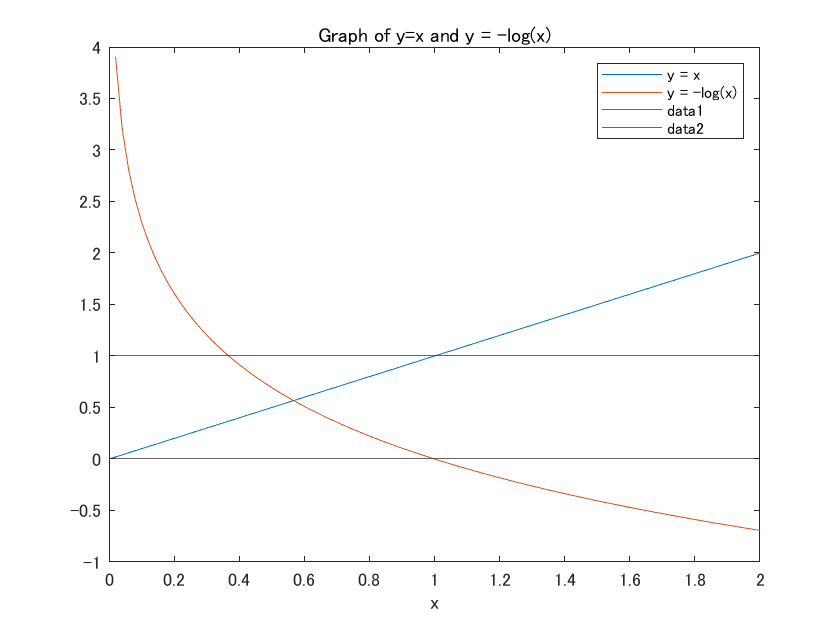

xs = linspace(0, 2, 100);
ys1 = xs;
ys2 = -log(xs);

figure(1);

plot(xs, ys1);
hold on
plot(xs, ys2);
legend(["y = x", "y = -log(x)"])
title("Graph of y=x and y = -log(x)");
xlabel("x");
yline(0)
yline(1)
hold off

(c)

x0 = 0.5;
xs = [x0];
i = 2;

err = 1e-3;
max_ite = 1000;

while true
    x1 = -log(x0);
    xs(i) = x1;
    i = i + 1;
    if abs(x1 - x0) < err || i >= max_ite + 2
        break;
    end
    x0 = x1;
end
disp("Result: " + x1)

Result: -0.72282+1.9293i


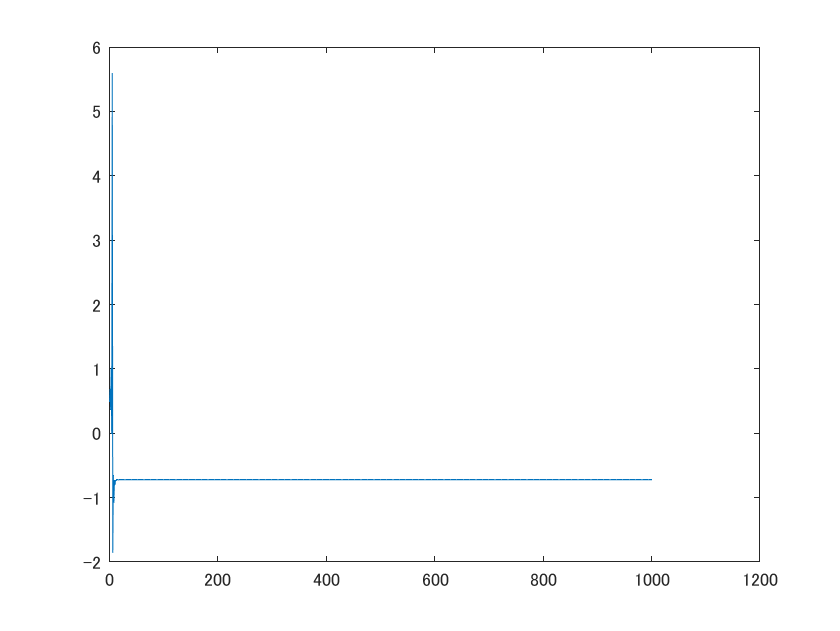


figure(2)

plot(1:length(xs), xs)

(d)

% from x0 = 1/2
x0 = 0.5;

xs = [x0];
i = 2;

err = 1e-9;
max_ite = 10;

while true
    x1 = -log(x0);
    xs(i) = x1;
    i = i + 1;
    if abs(x1 - x0) < err || i >= max_ite + 2
        break;
    end
    x0 = x1;
end
disp("Result: " + x1)

Result: -0.8058+1.9077i


%disp(xs)

% from x0 = 3/4
x0 = 0.75;
xs = [x0];
i = 2;

err = 1e-9;
max_ite = 10;

while true
    x1 = -log(x0);
    xs(i) = x1;
    i = i + 1;
    if abs(x1 - x0) < err || i >= max_ite + 2
        break;
    end
    x0 = x1;
end
disp("Result: " + x1)

Result: -0.71644-1.9549i


%disp(xs)

Both of the two iterations doesn't converge since from some point $x_n$ becomes complex.

(e) direct method

xz = 0.5671432904097838;

% from x0 = 1/2
x0 = 0.5;
xs = [x0];
i = 2;

err = 1e-9;
max_ite = 100;

f = @(x) x + log(x);

while true
    x1 = x0 - f(x0) / (1 - 1 / xz);
    xs(i) = x1;
    i = i + 1;
    if abs(x1 - x0) < err || i >= max_ite + 2
        break;
    end
    x0 = x1;
end
disp("Result: " + x1)

Result: -5.949418685711501e+34+1.150226920866022e+36i


disp(xs)

   1.0e+36 *

  1 列

  0.000000000000000 + 0.000000000000000i

  2 列

  0.000000000000000 + 0.000000000000000i

  3 列

 -0.000000000000000 + 0.000000000000000i

  4 列

 -0.000000000000000 + 0.000000000000000i

  5 列

 -0.000000000000000 + 0.000000000000000i

  6 列

 -0.000000000000000 + 0.000000000000000i

  7 列

 -0.000000000000000 + 0.000000000000000i

  8 列

 -0.000000000000000 + 0.000000000000000i

  9 列

 -0.000000000000000 + 0.000000000000000i

  10 列

 -0.000000000000000 + 0.000000000000000i

  11 列

 -0.000000000000000 + 0.000000000000000i

  12 列

 -0.000000000000000 + 0.000000000000000i

  13 列

 -0.000000000000000 + 0.000000000000000i

  14 列

 -0.000000000000000 + 0.000000000000000i

  15 列

 -0.000000000000000 + 0.000000000000000i

  16 列

 -0.000000000000000 + 0.000000000000000i

  17 列

 -0.000000000000000 + 0.000000000000000i

  18 列

 -0.000000000000000 + 0.000000000000000i

  19 列

 -0.000000000000000 + 0.000000000000000i

  20 列

 -0.000000000000000 + 0.0000000000000

# Problem 3

(c)

% from x0 = 3.5
x0 = 3.5;
xs = [x0];
i = 2;

err = 1e-9;
max_ite = 1000;

f = @(x) 3 * x ^2 - exp(x);
fp = @(x) 6 * x - exp(x);

while true
    x1 = x0 - f(x0) / fp(x0);
    xs(i) = x1;
    i = i + 1;
    if abs(x1 - x0) < err || i >= max_ite + 2
        break;
    end
    x0 = x1;
end
disp(xs)

  1 列から 2 列

   3.500000000000000   3.799992773996356

  3 列から 4 列

   3.736934820620055   3.733092686537753

  5 列から 6 列

   3.733079028804883   3.733079028632814




disp("Final Estimate of the Root: " + x1)

Final Estimate of the Root: 3.7331


# Problem 4

(a)

xs = [1.02, 0.95, 0.77, 0.67, 0.56, 0.30, 0.16, 0.01]';
ys = [0.39, 0.32, 0.22, 0.18, 0.15, 0.12, 0.13, 0.15]';

A = [ys.^2 xs.*ys xs ys ones(length(xs),1)];
b = xs.^2;

Ap = qr_house(A);
R = triu(Ap);
% R = R(1:min(size(R)), 1:min(size(R)))
L = tril(Ap);

[n,m] = size(A);
I = eye(n);
Q = eye(n);
for k = 1:min(n-1,m)
	L(k,k) = 1;
    v = L(:, k);
    Q = Q * (I - 2 / (v' * v) * (v * v'));
end

coeffs = R \ (Q' * b);

f = @(x, y) [y.^2, x.*y, x, y, 1] * coeffs - x.^2;

figure(3);
fimplicit(f)

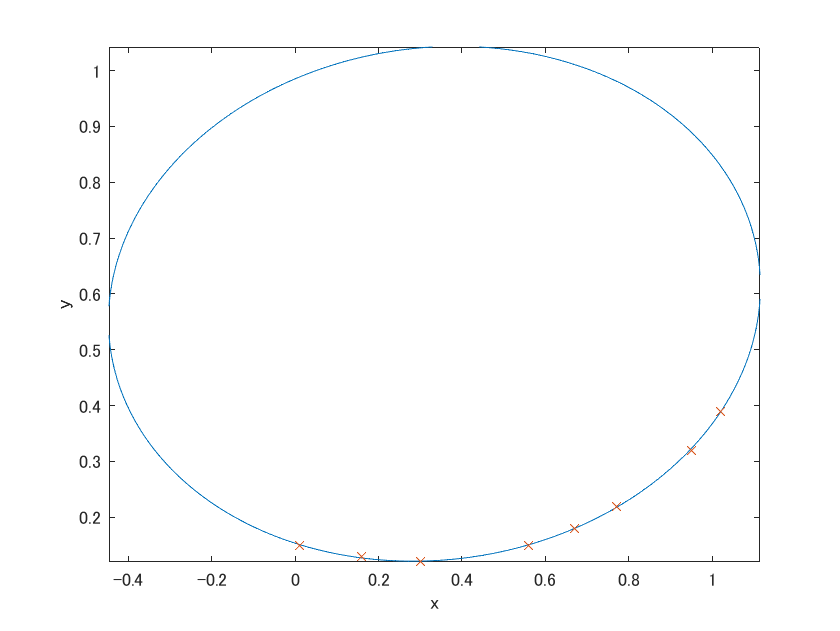

hold on
plot(xs, ys, 'x')
xlabel("x")
ylabel("y")
hold off

(b)

dxs = [1.2e-3 6.4e-3 -4.8e-3 2.8e-3 -1.4e-3 3.2e-3 3.6e-3 -9.0e-4];
dys = [-4.8e-3 1.9e-3 3.2e-3 4.8e-3 -2.1e-3 2.4e-3 -5.0e-3 2.2e-3];

xsp = xs + dxs';
ysp = ys + dys';

A2 = [ysp.^2 xsp.*ysp xsp ysp ones(length(xsp),1)];
b2 = xsp.^2;

Ap2 = qr_house(A2);
R2 = triu(Ap2);
L2 = tril(Ap2);

[n,m] = size(A2);
I2 = eye(n);
Q2 = eye(n);
for k = 1:min(n-1,m)
	L2(k,k) = 1;
    v = L2(:, k);
    Q2 = Q2 * (I2 - 2 / (v' * v) * (v * v'));
end

coeffs2 = R2 \ (Q2' * b2);

f2 = @(x, y) [y.^2, x.*y, x, y, 1] * coeffs2 - x.^2;

figure(4);
fimplicit(f)

hold on

fimplicit(f2)

plot(xs, ys, 'o')

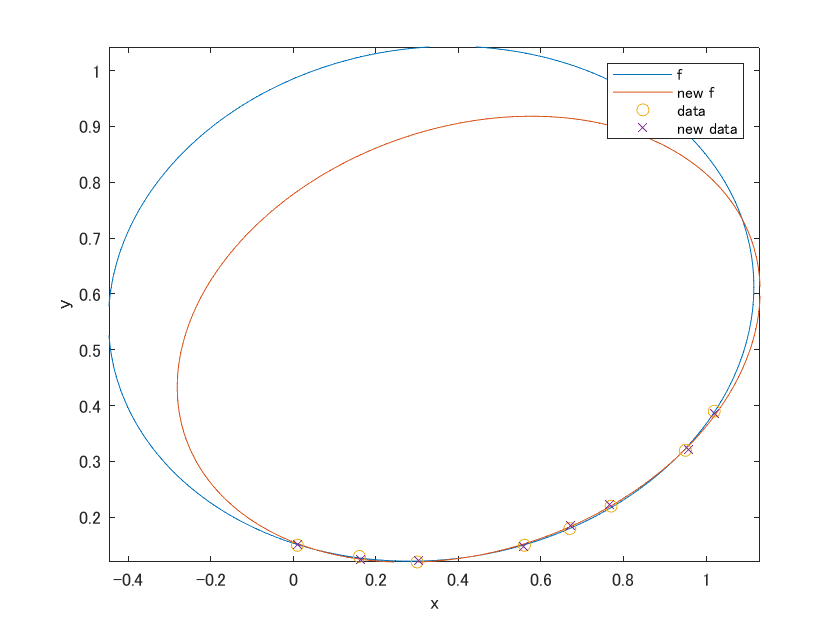

plot(xsp, ysp, 'x')
xlabel("x")
ylabel("y")
legend(["f", "new f", "data", "new data"])
hold off


format long 
disp("change in coefficient:")

change in coefficient:


norm(coeffs - coeffs2)

ans =    0.697944739993515


As we can see from the graph, after pertubating, the size of changes of parameter is much larger than the changes of data. And the orbit also change a lot. The result implies the unstability of such regression.

This is due to 2 factors:

- our data is sample on only one side of the ellipse, the other side is totally uncontroled when doing fitting.

- our data is sample from a ellipse who has a low curvature and the sample side is the size of low curvature of this specific ellipse, therefore a small change may lead to large error.

we can verify that our coefficient matrix has a large condition number, and the least squares problem is nearly rank-deficient, which implies that the linear equation problem is unstable.

disp("condition number of A/A2:")

condition number of A/A2:


cond(A)

ans =      6.807764588524919e+02


cond(A2)

ans =      6.914424284953905e+02


# Functions

function [A] = qr_house(A)
    % input:   A - (n x m) matrix 
    % output:  A - matrix containing the necessary information of the Householder
    %              vectors v in the lower triangle and R in the upper triangle
    
    % Author     : Stefan Hüeber
    % Date       : May, 8, 2003
    % Institution: University of Stuttgart,
    %              Institut for Applied Analysis and Numerical Mathematics,
    %              High Performance Scientific Computing
    % Version    : 1.0
    
    [n,m] = size(A);
    for k = 1:min(n-1,m)
    	v(k:n,1) = HOUSEHOLDER(A(k:n,k));
    	A(k:n,k:m) = HOUSEHOLDER_MULT(A(k:n,k:m),v(k:n,1));
        %disp(v)
    	A(k+1:n,k) = v(k+1:n,1);
    end
end

function [v] = HOUSEHOLDER(a)
    % input:   a - vector with a \neq 0
    % output:  v - Householder vector of x such that v_1 = 1
    
    % Author     : Stefan Hüeber
    % Date       : May, 8, 2003
    % Institution: University of Stuttgart,
    %              Institut for Applied Analysis and Numerical Mathematics,
    %              High Performance Scientific Computing
    % Version    : 1.0
    
    n = length(a);
    v = a;
    if (a(1) >= 0) 
        beta = a(1) + norm(a);
    else 
        beta = a(1) - norm(a);
    end
    v(2:n) = 1/beta * v(2:n);
    v(1) = 1;
end

function [A] = HOUSEHOLDER_MULT(A,v)
    % input:   A - matrix
    %          v - Householder vector 
    % output:  A - transformed matrix 
    %              A = A - \(\frac{\text{2}}{\text{v'v}}(\text{vv'})\)A 
    
    % Author     : Stefan Hüeber
    % Date       : May, 8, 2003
    % Institution: University of Stuttgart,
    %              Institut for Applied Analysis and Numerical Mathematics,
    %              High Performance Scientific Computing
    % Version    : 1.0
    
    beta = -2/(v'*v);
    w = v'*A;          % w is a line vector
    A = A + beta*v*w;
end